clear
close all
clc

%% 5.1 Parameters and nominal operating point

a = 1.2272*ones(4,1);
A_tank = 380.1327*ones(4,1);
gamma = [0.6;0.7];
g = 981;
rho = 1;

p = [a;A_tank;gamma;g;rho];

us = [300;300];
Fbar = [175;175];

xs = fsolve(@(x) FourTankSystem(0,x,us,Fbar,p), ...
    10000*ones(4,1),optimoptions('fsolve','Display','none'));

hs = FourTankSensors(xs,p);
zs = FourTankOutputs(xs,p);

fprintf('Nominal state x_s:\n')

Nominal state x_s:


disp(xs)

   1.0e+04 *

    2.5476
    3.2809
    0.9034
    1.1196




fprintf('Nominal levels h_s:\n')

Nominal levels h_s:


disp(hs)

   67.0178
   86.3084
   23.7663
   29.4520




fprintf('Nominal outputs z_s:\n')

Nominal outputs z_s:


disp(zs)

   67.0178
   86.3084





%% 5.2 Continuous-time linearized models

lambda = a./A_tank.*sqrt(g./(2*hs));

A4 = [
    -lambda(1),0,lambda(3),0
    0,-lambda(2),0,lambda(4)
    0,0,-lambda(3),0
    0,0,0,-lambda(4)
];

Bu = rho*[
    gamma(1),0
    0,gamma(2)
    0,1-gamma(2)
    1-gamma(1),0
];

Ec = rho*[
    0,0
    0,0
    1,0
    0,1
];

Cy = diag(1./(rho*A_tank));

Dy = zeros(4,2);

% Disturbance deviations
% Deterministic model: F3 and F4 remain constant
% Therefore, Delta F3 = Delta F4 = 0.


%% PWC model

A_PWC = A4;
B_PWC = Bu;
E_PWC = Ec;
C_PWC = Cy;
D_PWC = Dy;

F_PWC = zeros(4,2);

sys_c_PWC_u = ss(A_PWC,B_PWC,C_PWC,D_PWC);
sys_c_PWC_d = ss(A_PWC,E_PWC,C_PWC,F_PWC);

G_c_PWC_u = tf(sys_c_PWC_u);
G_c_PWC_d = tf(sys_c_PWC_d);


%% Deterministic model - Exercise 4
% F3 and F4 are kept constant, so their deviations are zero.

A_Det = A4;
B_Det = Bu;
E_Det = Ec;
C_Det = Cy;
D_Det = Dy;

F_Det = zeros(4,2);

sys_c_Det_u = ss(A_Det,B_Det,C_Det,D_Det);
sys_c_Det_d = ss(A_Det,E_Det,C_Det,F_Det);

G_c_Det_u = tf(sys_c_Det_u);
G_c_Det_d = tf(sys_c_Det_d);


%% Ornstein-Uhlenbeck model

tau_F = 40;
a_F = 1/tau_F;

sigma_F = 17.5;
sigma_OU = sigma_F*sqrt(2*a_F);

A_OU = [
    A4, Ec
    zeros(2,4), -a_F*eye(2)
];

B_OU = [
    Bu
    zeros(2,2)
];

% Noise enters the two additional disturbance states
G_OU = [
    zeros(4,2)
    sigma_OU*eye(2)
];

C_OU = [Cy zeros(4,2)];
D_OU = zeros(4,2);

sys_c_OU_u = ss(A_OU,B_OU,C_OU,D_OU);
sys_c_OU_w = ss(A_OU,G_OU,C_OU,zeros(4,2));

G_c_OU_u = tf(sys_c_OU_u);
G_c_OU_w = tf(sys_c_OU_w);


%% Display continuous-time matrices

fprintf('\n================ PWC MODEL ================\n')


================ PWC MODEL ================


disp('A_PWC =')

A_PWC =


disp(A_PWC)

   -0.0087         0    0.0147         0
         0   -0.0077         0    0.0132
         0         0   -0.0147         0
         0         0         0   -0.0132



disp('B_PWC =')

B_PWC =


disp(B_PWC)

    0.6000         0
         0    0.7000
         0    0.3000
    0.4000         0



disp('E_PWC =')

E_PWC =


disp(E_PWC)

     0     0
     0     0
     1     0
     0     1



disp('C_PWC =')

C_PWC =


disp(C_PWC)

    0.0026         0         0         0
         0    0.0026         0         0
         0         0    0.0026         0
         0         0         0    0.0026




fprintf('\n================ DETERMINISTIC MODEL ================\n')


================ DETERMINISTIC MODEL ================


disp('A_Det =')

A_Det =


disp(A_Det)

   -0.0087         0    0.0147         0
         0   -0.0077         0    0.0132
         0         0   -0.0147         0
         0         0         0   -0.0132



disp('B_Det =')

B_Det =


disp(B_Det)

    0.6000         0
         0    0.7000
         0    0.3000
    0.4000         0



disp('E_Det =')

E_Det =


disp(E_Det)

     0     0
     0     0
     1     0
     0     1



disp('C_Det =')

C_Det =


disp(C_Det)

    0.0026         0         0         0
         0    0.0026         0         0
         0         0    0.0026         0
         0         0         0    0.0026




fprintf('\n================ OU MODEL ================\n')


================ OU MODEL ================


disp('A_OU =')

A_OU =


disp(A_OU)

   -0.0087         0    0.0147         0         0         0
         0   -0.0077         0    0.0132         0         0
         0         0   -0.0147         0    1.0000         0
         0         0         0   -0.0132         0    1.0000
         0         0         0         0   -0.0250         0
         0         0         0         0         0   -0.0250



disp('B_OU =')

B_OU =


disp(B_OU)

    0.6000         0
         0    0.7000
         0    0.3000
    0.4000         0
         0         0
         0         0



disp('G_OU =')

G_OU =


disp(G_OU)

         0         0
         0         0
         0         0
         0         0
    3.9131         0
         0    3.9131



disp('C_OU =')

C_OU =


disp(C_OU)

    0.0026         0         0         0         0         0
         0    0.0026         0         0         0         0
         0         0    0.0026         0         0         0
         0         0         0    0.0026         0         0





%% 5.3 Continuous-time transfer functions

fprintf('\nPWC model: u -> y\n')


PWC model: u -> y


G_c_PWC_u


G_c_PWC_u =
 
  From input 1 to output...
         0.001578
   1:  ------------
       s + 0.008734
 
                1.386e-05
   2:  ---------------------------
       s^2 + 0.02087 s + 0.0001014
 
   3:  0
 
        0.001052
   4:  -----------
       s + 0.01317
 
  From input 2 to output...
               1.157e-05
   1:  --------------------------
       s^2 + 0.0234 s + 0.0001281
 
         0.001841
   2:  ------------
       s + 0.007696
 
        0.0007892
   3:  -----------
       s + 0.01467
 
   4:  0
 
Continuous-time transfer function.



fprintf('\nDeterministic model: u -> y\n')


Deterministic model: u -> y


G_c_Det_u


G_c_Det_u =
 
  From input 1 to output...
         0.001578
   1:  ------------
       s + 0.008734
 
                1.386e-05
   2:  ---------------------------
       s^2 + 0.02087 s + 0.0001014
 
   3:  0
 
        0.001052
   4:  -----------
       s + 0.01317
 
  From input 2 to output...
               1.157e-05
   1:  --------------------------
       s^2 + 0.0234 s + 0.0001281
 
         0.001841
   2:  ------------
       s + 0.007696
 
        0.0007892
   3:  -----------
       s + 0.01467
 
   4:  0
 
Continuous-time transfer function.



fprintf('\nOU model: u -> y\n')


OU model: u -> y


G_c_OU_u


G_c_OU_u =
 
  From input 1 to output...
         0.001578
   1:  ------------
       s + 0.008734
 
                1.386e-05
   2:  ---------------------------
       s^2 + 0.02087 s + 0.0001014
 
   3:  0
 
        0.001052
   4:  -----------
       s + 0.01317
 
  From input 2 to output...
               1.157e-05
   1:  --------------------------
       s^2 + 0.0234 s + 0.0001281
 
         0.001841
   2:  ------------
       s + 0.007696
 
        0.0007892
   3:  -----------
       s + 0.01467
 
   4:  0
 
Continuous-time transfer function.



fprintf('\nPWC disturbance transfer functions:\n')


PWC disturbance transfer functions:


G_c_PWC_d


G_c_PWC_d =
 
  From input 1 to output...
               3.858e-05
   1:  --------------------------
       s^2 + 0.0234 s + 0.0001281
 
   2:  0
 
        0.002631
   3:  -----------
       s + 0.01467
 
   4:  0
 
  From input 2 to output...
   1:  0
 
                3.466e-05
   2:  ---------------------------
       s^2 + 0.02087 s + 0.0001014
 
   3:  0
 
        0.002631
   4:  -----------
       s + 0.01317
 
Continuous-time transfer function.



fprintf('\nDeterministic disturbance transfer functions:\n')


Deterministic disturbance transfer functions:


G_c_Det_d


G_c_Det_d =
 
  From input 1 to output...
               3.858e-05
   1:  --------------------------
       s^2 + 0.0234 s + 0.0001281
 
   2:  0
 
        0.002631
   3:  -----------
       s + 0.01467
 
   4:  0
 
  From input 2 to output...
   1:  0
 
                3.466e-05
   2:  ---------------------------
       s^2 + 0.02087 s + 0.0001014
 
   3:  0
 
        0.002631
   4:  -----------
       s + 0.01317
 
Continuous-time transfer function.



fprintf('\nOU noise transfer functions:\n')


OU noise transfer functions:


G_c_OU_w


G_c_OU_w =
 
  From input 1 to output...
                        0.000151
   1:  ------------------------------------------
       s^3 + 0.0484 s^2 + 0.0007131 s + 3.202e-06
 
   2:  0
 
                 0.01029
   3:  ---------------------------
       s^2 + 0.03967 s + 0.0003667
 
   4:  0
 
  From input 2 to output...
   1:  0
 
                        0.0001356
   2:  -------------------------------------------
       s^3 + 0.04587 s^2 + 0.0006232 s + 2.535e-06
 
   3:  0
 
                 0.01029
   4:  ---------------------------
       s^2 + 0.03817 s + 0.0003294
 
Continuous-time transfer function.




%% Compare manipulated-input transfer functions

modelNames = ["PWC";"Deterministic";"OU"];

G_linearized = {
    G_c_PWC_u
    G_c_Det_u
    G_c_OU_u
};

transferFunctionNames = [
    "G11";"G12"
    "G21";"G22"
    "G31";"G32"
    "G41";"G42"
];

nModels = numel(G_linearized);
nTF = numel(transferFunctionNames);

for m = 1:nModels
    for i = 1:4
        for j = 1:2

            fprintf('%s - %s\n',modelNames(m), ...
                transferFunctionNames(2*(i-1)+j));

        end
    end
end

PWC - G11
PWC - G12
PWC - G21
PWC - G22
PWC - G31
PWC - G32
PWC - G41
PWC - G42
Deterministic - G11
Deterministic - G12
Deterministic - G21
Deterministic - G22
Deterministic - G31
Deterministic - G32
Deterministic - G41
Deterministic - G42
OU - G11
OU - G12
OU - G21
OU - G22
OU - G31
OU - G32
OU - G41
OU - G42



error_PWC_Det = norm(G_c_PWC_u-G_c_Det_u);
error_PWC_OU = norm(G_c_PWC_u-G_c_OU_u);

fprintf('\nPWC-Deterministic transfer function error: %.3e\n', ...
    error_PWC_Det)


PWC-Deterministic transfer function error: 0.000e+00



fprintf('PWC-OU transfer function error: %.3e\n', ...
    error_PWC_OU)

PWC-OU transfer function error: 0.000e+00




%% Calculate continuous-time gains and time constants

Gain_CT = zeros(nModels,nTF);
Tau_CT = NaN(nModels,nTF);

for m = 1:nModels

    for i = 1:4
        for j = 1:2

            k = 2*(i-1)+j;

            Gij = minreal(G_linearized{m}(i,j));

            Gain_CT(m,k) = dcgain(Gij);

            stablePoles = pole(Gij);
            stablePoles = stablePoles(real(stablePoles) < -1e-9);

            if ~isempty(stablePoles)
                Tau_CT(m,k) = max(-1./real(stablePoles));
            end

        end
    end
end


%% Export linearized continuous-time results

ModelColumn = strings(nModels*nTF,1);
TransferFunctionColumn = strings(nModels*nTF,1);
GainColumn = zeros(nModels*nTF,1);
TauColumn = NaN(nModels*nTF,1);

row = 0;

for m = 1:nModels
    for k = 1:nTF

        row = row+1;

        ModelColumn(row) = modelNames(m);
        TransferFunctionColumn(row) = transferFunctionNames(k);

        GainColumn(row) = Gain_CT(m,k);
        TauColumn(row) = Tau_CT(m,k);

    end
end

LinearizedTable = table( ...
    ModelColumn, ...
    TransferFunctionColumn, ...
    GainColumn, ...
    TauColumn, ...
    'VariableNames', ...
    {'Model','TransferFunction','Gain_CT','DominantTau_s'});

disp('Continuous-time parameters:')

Continuous-time parameters:


disp(LinearizedTable)

         Model         TransferFunction    Gain_CT     DominantTau_s
    _______________    ________________    ________    _____________

    "PWC"                   "G11"           0.18072        114.5    
    "PWC"                   "G12"          0.090361        114.5    
    "PWC"                   "G21"           0.13673       129.94    
    "PWC"                   "G22"           0.23927       129.94    
    "PWC"                   "G31"                 0          NaN    
    "PWC"                   "G32"          0.053811       68.184    
    "PWC"                   "G41"           0.07987       75.903    
    "PWC"                   "G42"                 0          NaN    
    "Deterministic"         "G11"           0.18072        114.5    
    "Deterministic"         "G12"          0.090361        114.5    
    "Deterministic"         "G21"  


filename = 'TF_Parameters.xlsx';

writetable(LinearizedTable,filename, ...
    'Sheet','P5 Linearized CT');


%% Read deterministic identification from Exercise 4

Table_Deterministic = readtable(filename, ...
    'Sheet','Deterministic 1st Order');

Gain_Reference = zeros(nTF,1);
Tau_Reference = zeros(nTF,1);

for k = 1:nTF

    name = transferFunctionNames(k);

    idx = find( ...
        string(Table_Deterministic.TransferFunction) == name,1);

    if isempty(idx)
        error('Transfer function %s not found in Excel.',name)
    end

    Gain_Reference(k) = Table_Deterministic.Gain(idx);
    Tau_Reference(k) = Table_Deterministic.Tau_s(idx);

end


%% Compare gains and time constants with Exercise 4

GainError = zeros(nModels,nTF);
GainRelativeError = zeros(nModels,nTF);

TauError = NaN(nModels,nTF);
TauRelativeError = NaN(nModels,nTF);

for m = 1:nModels

    for k = 1:nTF

        GainError(m,k) = ...
            Gain_CT(m,k)-Gain_Reference(k);

        GainRelativeError(m,k) = ...
            100*abs(GainError(m,k))/abs(Gain_Reference(k));

        if ~isnan(Tau_CT(m,k))

            TauError(m,k) = ...
                Tau_CT(m,k)-Tau_Reference(k);

            TauRelativeError(m,k) = ...
                100*abs(TauError(m,k))/abs(Tau_Reference(k));

        end

    end
end


%% Comparison table

ComparisonTable = table( ...
    repelem(modelNames,nTF), ...
    repmat(transferFunctionNames,nModels,1), ...
    reshape(Gain_CT.',[],1), ...
    reshape(Tau_CT.',[],1), ...
    repmat(Gain_Reference,nModels,1), ...
    repmat(Tau_Reference,nModels,1), ...
    reshape(GainRelativeError.',[],1), ...
    reshape(TauRelativeError.',[],1), ...
    'VariableNames', ...
    {'Model','TransferFunction', ...
    'Gain_Model','Tau_Model_s', ...
    'Gain_Exercise4','Tau_Exercise4_s', ...
    'GainRelativeError_percent', ...
    'TauRelativeError_percent'});

disp('Comparison with Exercise 4:')

Comparison with Exercise 4:


disp(ComparisonTable)

         Model         TransferFunction    Gain_Model    Tau_Model_s    Gain_Exercise4    Tau_Exercise4_s    GainRelativeError_percent    TauRelativeError_percent
    _______________    ________________    __________    ___________    ______________    _______________    _________________________    ________________________

    "PWC"                   "G11"            0.18072        114.5            0.18498           128.4                  2.3039                       10.827         
    "PWC"                   "G12"           0.090361        114.5           0.093982          205.47                  3.8525                       44.276         
    "PWC"                   "G21"            0.13673       129.94          


writetable(ComparisonTable,filename, ...
    'Sheet','P5 Comparison');


%% PLOT 1: Step Response Comparison
% Three models compared with the deterministic identification from Exercise 4

set(groot,'defaultFigureWindowStyle','normal');

fig1 = figure( ...
    'Name','Step Response Comparison', ...
    'NumberTitle','off', ...
    'Color','w', ...
    'WindowStyle','normal');

timePlot = (0:1:1200)';

for i = 1:4
    for j = 1:2

        k = 2*(i-1)+j;

        subplot(4,2,k)

        [yPWC,~] = step(G_c_PWC_u(i,j),timePlot);
        [yDet,~] = step(G_c_Det_u(i,j),timePlot);
        [yOU,~] = step(G_c_OU_u(i,j),timePlot);

        plot(timePlot,squeeze(yPWC), ...
            'LineWidth',1.4, ...
            'DisplayName','PWC');

        hold on

        plot(timePlot,squeeze(yDet), ...
            '--','LineWidth',1.4, ...
            'DisplayName','Deterministic');

        plot(timePlot,squeeze(yOU), ...
            ':','LineWidth',1.6, ...
            'DisplayName','OU');

        Gref = tf(Gain_Reference(k), ...
            [Tau_Reference(k) 1]);

        [yRef,~] = step(Gref,timePlot);

        plot(timePlot,squeeze(yRef), ...
            '-.','LineWidth',1.4, ...
            'DisplayName','Exercise 4 identification');

        set(gca,'Color','w','XColor','k','YColor','k');

        grid on
        xlabel('Time [s]')
        ylabel('Output deviation')
        title(transferFunctionNames(k),'Color','k')

        lgd = legend('Location','best');

        set(lgd,'Color','w','TextColor','k', ...
            'EdgeColor',[0.3 0.3 0.3]);

    end
end

sgtitle('Unit-Step Response Comparison','Color','k');


%% 5.4 Discrete-time state-space models

Ts_disc = 4;


%% PWC model - ZOH discretization

% Discretize manipulated inputs and external disturbances together
sys_c_PWC_all = ss( ...
    A_PWC,[B_PWC E_PWC], ...
    C_PWC,zeros(4,4));

sys_d_PWC_all = c2d(sys_c_PWC_all,Ts_disc,'zoh');

A_d_PWC = sys_d_PWC_all.A;
B_d_PWC = sys_d_PWC_all.B(:,1:2);
E_d_PWC = sys_d_PWC_all.B(:,3:4);

C_d_PWC = C_PWC;
D_d_PWC = zeros(4,2);

sys_d_PWC_u = ss( ...
    A_d_PWC,B_d_PWC,C_d_PWC,D_d_PWC,Ts_disc);


%% Deterministic model - ZOH discretization

sys_c_Det_all = ss( ...
    A_Det,[B_Det E_Det], ...
    C_Det,zeros(4,4));

sys_d_Det_all = c2d(sys_c_Det_all,Ts_disc,'zoh');

A_d_Det = sys_d_Det_all.A;
B_d_Det = sys_d_Det_all.B(:,1:2);
E_d_Det = sys_d_Det_all.B(:,3:4);

C_d_Det = C_Det;
D_d_Det = zeros(4,2);

sys_d_Det_u = ss( ...
    A_d_Det,B_d_Det,C_d_Det,D_d_Det,Ts_disc);


%% OU model - ZOH discretization

% Discretize manipulated inputs and OU noise inputs together
sys_c_OU_all = ss( ...
    A_OU,[B_OU G_OU], ...
    C_OU,zeros(4,4));

sys_d_OU_all = c2d(sys_c_OU_all,Ts_disc,'zoh');

A_d_OU = sys_d_OU_all.A;
B_d_OU = sys_d_OU_all.B(:,1:2);
G_d_OU = sys_d_OU_all.B(:,3:4);

C_d_OU = C_OU;
D_d_OU = zeros(4,2);

sys_d_OU_u = ss( ...
    A_d_OU,B_d_OU,C_d_OU,D_d_OU,Ts_disc);


%% Display discrete-time matrices

fprintf('\n================ PWC DISCRETE MODEL ================\n')


================ PWC DISCRETE MODEL ================



disp('A_d_PWC =')

A_d_PWC =


disp(A_d_PWC)

    0.9657         0    0.0560         0
         0    0.9697         0    0.0505
         0         0    0.9430         0
         0         0         0    0.9487




disp('B_d_PWC =')

B_d_PWC =


disp(B_d_PWC)

    2.3586    0.0341
    0.0410    2.7573
         0    1.1655
    1.5586         0




disp('E_d_PWC =')

E_d_PWC =


disp(E_d_PWC)

    0.1137         0
         0    0.1025
    3.8849         0
         0    3.8964




disp('C_d_PWC =')

C_d_PWC =


disp(C_d_PWC)

    0.0026         0         0         0
         0    0.0026         0         0
         0         0    0.0026         0
         0         0         0    0.0026





fprintf('\n================ DETERMINISTIC DISCRETE MODEL ================\n')


================ DETERMINISTIC DISCRETE MODEL ================



disp('A_d_Det =')

A_d_Det =


disp(A_d_Det)

    0.9657         0    0.0560         0
         0    0.9697         0    0.0505
         0         0    0.9430         0
         0         0         0    0.9487




disp('B_d_Det =')

B_d_Det =


disp(B_d_Det)

    2.3586    0.0341
    0.0410    2.7573
         0    1.1655
    1.5586         0




disp('E_d_Det =')

E_d_Det =


disp(E_d_Det)

    0.1137         0
         0    0.1025
    3.8849         0
         0    3.8964




disp('C_d_Det =')

C_d_Det =


disp(C_d_Det)

    0.0026         0         0         0
         0    0.0026         0         0
         0         0    0.0026         0
         0         0         0    0.0026





fprintf('\n================ OU DISCRETE MODEL ================\n')


================ OU DISCRETE MODEL ================



disp('A_d_OU =')

A_d_OU =


disp(A_d_OU)

    0.9657         0    0.0560         0    0.1100         0
         0    0.9697         0    0.0505         0    0.0992
         0         0    0.9430         0    3.6952         0
         0         0         0    0.9487         0    3.7063
         0         0         0         0    0.9048         0
         0         0         0         0         0    0.9048




disp('B_d_OU =')

B_d_OU =


disp(B_d_OU)

    2.3586    0.0341
    0.0410    2.7573
         0    1.1655
    1.5586         0
         0         0
         0         0




disp('G_d_OU =')

G_d_OU =


disp(G_d_OU)

    0.5833         0
         0    0.5253
   29.6986         0
         0   29.7576
   14.8953         0
         0   14.8953




disp('C_d_OU =')

C_d_OU =


disp(C_d_OU)

    0.0026         0         0         0         0         0
         0    0.0026         0         0         0         0
         0         0    0.0026         0         0         0
         0         0         0    0.0026         0         0





%% Compare eigenvalues

fprintf('\nPWC eigenvalues:\n')


PWC eigenvalues:


disp(eig(A_d_PWC))

    0.9657
    0.9697
    0.9430
    0.9487




fprintf('\nDeterministic eigenvalues:\n')


Deterministic eigenvalues:


disp(eig(A_d_Det))

    0.9657
    0.9697
    0.9430
    0.9487




fprintf('\nOU eigenvalues:\n')


OU eigenvalues:


disp(eig(A_d_OU))

    0.9657
    0.9697
    0.9430
    0.9487
    0.9048
    0.9048





%% 5.5 Markov parameters

N_markov = 300;

A_models = {
    A_d_PWC
    A_d_Det
    A_d_OU
};

B_models = {
    B_d_PWC
    B_d_Det
    B_d_OU
};

C_models = {
    C_d_PWC
    C_d_Det
    C_d_OU
};

D_models = {
    D_d_PWC
    D_d_Det
    D_d_OU
};

H_models = cell(nModels,1);

for m = 1:nModels

    H_models{m} = zeros(4,2,N_markov+1);

    H_models{m}(:,:,1) = D_models{m};

    for k = 1:N_markov

        H_models{m}(:,:,k+1) = ...
            C_models{m}*A_models{m}^(k-1)*B_models{m};

    end
end

H_PWC = H_models{1};
H_Det = H_models{2};
H_OU = H_models{3};


%% Build reference transfer-function matrix from Exercise 4

G_Reference = tf(zeros(4,2));

for i = 1:4
    for j = 1:2

        k = 2*(i-1)+j;

        G_Reference(i,j) = tf( ...
            Gain_Reference(k), ...
            [Tau_Reference(k) 1]);

    end
end


%% Discretize reference model

sys_c_Reference = ss(G_Reference);

sys_d_Reference = c2d( ...
    sys_c_Reference,Ts_disc,'zoh');

[A_d_Reference,B_d_Reference, ...
    C_d_Reference,D_d_Reference] = ssdata(sys_d_Reference);


%% Reference Markov parameters

H_Reference = zeros(4,2,N_markov+1);

H_Reference(:,:,1) = D_d_Reference;

for k = 1:N_markov

    H_Reference(:,:,k+1) = ...
        C_d_Reference*A_d_Reference^(k-1)*B_d_Reference;

end

tH_Reference = (0:N_markov)*Ts_disc;


%% Compare Markov parameters for the three models

H_models = {
    H_PWC
    H_Det
    H_OU
};

Markov_RMSE = zeros(nModels,nTF);
Markov_MaxError = zeros(nModels,nTF);
Markov_RelativeError = zeros(nModels,nTF);

for m = 1:nModels

    for i = 1:4
        for j = 1:2

            k = 2*(i-1)+j;

            hModel = squeeze(H_models{m}(i,j,:));
            hReference = squeeze(H_Reference(i,j,:));

            errorMarkov = hModel-hReference;

            Markov_MaxError(m,k) = max(abs(errorMarkov));

            Markov_RMSE(m,k) = ...
                sqrt(mean(errorMarkov.^2));

            if norm(hReference) > 0

                Markov_RelativeError(m,k) = ...
                    100*norm(errorMarkov)/norm(hReference);

            else

                Markov_RelativeError(m,k) = NaN;

            end

        end
    end
end


%% Markov comparison summary table

MarkovSummaryTable = table( ...
    repelem(modelNames,nTF), ...
    repmat(transferFunctionNames,nModels,1), ...
    reshape(Markov_MaxError.',[],1), ...
    reshape(Markov_RMSE.',[],1), ...
    reshape(Markov_RelativeError.',[],1), ...
    'VariableNames', ...
    {'Model','TransferFunction', ...
    'MaxError','RMSE','RelativeError_percent'});

disp('Markov parameter comparison:')

Markov parameter comparison:


disp(MarkovSummaryTable)

         Model         TransferFunction     MaxError        RMSE       RelativeError_percent
    _______________    ________________    __________    __________    _____________________

    "PWC"                   "G11"          0.00053061    9.0098e-05           6.7709        
    "PWC"                   "G12"           0.0017221    0.00022996           43.029        
    "PWC"                   "G21"           0.0023279    0.00032616           42.633        
    "PWC"                   "G22"          0.00054718    9.9499e-05           5.9805        
    "PWC"                   "G31"          7.4993e-10    8.0748e-11              100        
    "PWC"                   "G32"          0.00042536    5.6297e-05           11.335        
    "PWC"                   "G41"          0.00052331    7.2957e-05           10.354 

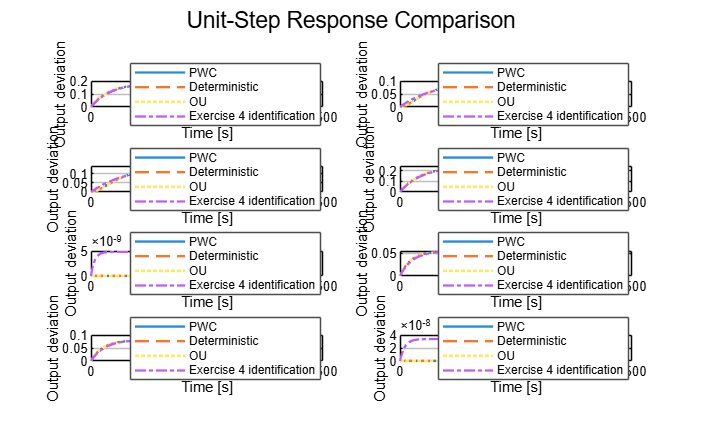


writetable(MarkovSummaryTable,filename, ...
    'Sheet','P5 Markov Summary');


%% Export all Markov parameters

nRows = nModels*8*(N_markov+1);

ModelColumn = strings(nRows,1);
TransferFunctionColumn = strings(nRows,1);
SampleColumn = zeros(nRows,1);
TimeColumn = zeros(nRows,1);

ModelMarkovColumn = zeros(nRows,1);
ReferenceMarkovColumn = zeros(nRows,1);
ErrorColumn = zeros(nRows,1);

row = 0;

for m = 1:nModels

    for i = 1:4
        for j = 1:2

            k = 2*(i-1)+j;

            for n = 1:N_markov+1

                row = row+1;

                ModelColumn(row) = modelNames(m);
                TransferFunctionColumn(row) = ...
                    transferFunctionNames(k);

                SampleColumn(row) = n-1;
                TimeColumn(row) = (n-1)*Ts_disc;

                ModelMarkovColumn(row) = ...
                    H_models{m}(i,j,n);

                ReferenceMarkovColumn(row) = ...
                    H_Reference(i,j,n);

                ErrorColumn(row) = ...
                    ModelMarkovColumn(row)-ReferenceMarkovColumn(row);

            end
        end
    end
end

MarkovComparisonTable = table( ...
    ModelColumn, ...
    TransferFunctionColumn, ...
    SampleColumn, ...
    TimeColumn, ...
    ModelMarkovColumn, ...
    ReferenceMarkovColumn, ...
    ErrorColumn, ...
    'VariableNames', ...
    {'Model','TransferFunction','Sample','Time_s', ...
    'Markov_Model','Markov_Exercise4','Error'});

writetable(MarkovComparisonTable,filename, ...
    'Sheet','P5 Markov Comparison');
set(gcf, 'Visible', 'on')
set(gcf, 'WindowStyle', 'normal')

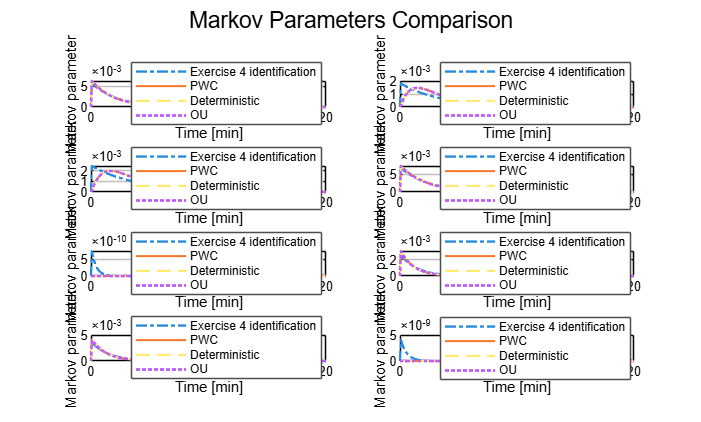



%% PLOT 2: Markov Parameters Comparison
% Three models compared with the deterministic identification from Exercise 4

fig2 = figure( ...
    'Name','Markov Parameters Comparison', ...
    'NumberTitle','off', ...
    'Color','w', ...
    'WindowStyle','normal');

for i = 1:4
    for j = 1:2

        k = 2*(i-1)+j;

        subplot(4,2,k)

        plot(tH_Reference/60, ...
            squeeze(H_Reference(i,j,:)), ...
            '-.','LineWidth',1.4, ...
            'DisplayName','Exercise 4 identification');

        hold on

        plot((0:N_markov)*Ts_disc/60, ...
            squeeze(H_PWC(i,j,:)), ...
            'LineWidth',1.2, ...
            'DisplayName','PWC');

        plot((0:N_markov)*Ts_disc/60, ...
            squeeze(H_Det(i,j,:)), ...
            '--','LineWidth',1.2, ...
            'DisplayName','Deterministic');

        plot((0:N_markov)*Ts_disc/60, ...
            squeeze(H_OU(i,j,:)), ...
            ':','LineWidth',1.6, ...
            'DisplayName','OU');

        set(gca,'Color','w','XColor','k','YColor','k');

        grid on
        xlabel('Time [min]')
        ylabel('Markov parameter')
        title(transferFunctionNames(k),'Color','k')

        lgd = legend('Location','best');

        set(lgd,'Color','w','TextColor','k', ...
            'EdgeColor',[0.3 0.3 0.3]);

    end
end

sgtitle('Markov Parameters Comparison','Color','k');
set(gcf, 'Visible', 'on')
set(gcf, 'WindowStyle', 'normal')



%% Final comparison between the three models

error_PWC_Det_Markov = ...
    max(abs(H_PWC(:)-H_Det(:)));

error_PWC_OU_Markov = ...
    max(abs(H_PWC(:)-H_OU(:)));

fprintf('\nPWC-Deterministic Markov maximum error: %.3e\n', ...
    error_PWC_Det_Markov)


PWC-Deterministic Markov maximum error: 0.000e+00



fprintf('PWC-OU Markov maximum error: %.3e\n', ...
    error_PWC_OU_Markov)

PWC-OU Markov maximum error: 8.674e-19




%% Save discrete-time models and results

save('Problem5_Models.mat', ...
    'A_d_PWC','B_d_PWC','E_d_PWC','C_d_PWC','D_d_PWC', ...
    'A_d_Det','B_d_Det','E_d_Det','C_d_Det','D_d_Det', ...
    'A_d_OU','B_d_OU','G_d_OU','C_d_OU','D_d_OU', ...
    'H_PWC','H_Det','H_OU','H_Reference', ...
    'MarkovSummaryTable','ComparisonTable', ...
    'Ts_disc','N_markov');